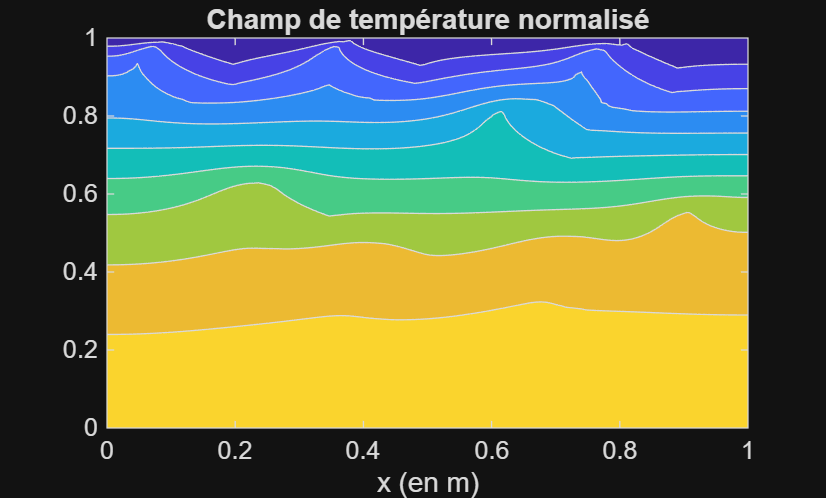


%-------------------------- Code Percolation en conduction thermique 2D--------------------------------------

%----------------------- -------------Cas hétérogène ------------------------------------------------------


clear all;
close all;


Tetc = 1; %Température haut
Tetf = 0; %Température bas
Lx = 1; %Longueur x
Ly = 1; %Longueur y
r = 10; % Rayon des charges
fs = 0.2; % Fraction surfacique de charges
kc = 10; % Conductivité charges
ki = 1; % Conductivité isolant
Nx = 128; % Nb de points x
Ny = 128; %Nb de points y
N = Nx*Ny;

dx=Lx/(Nx-1); %Pas x
dy=Ly/(Ny-1); %Pas y

[k, Fs, filename]= PercolationGenerator(Nx, Ny, r, fs, false); %Conductivité thermique


k = ki + k*(kc-ki); % On remplit la matrice avec les valeurs de conductivité

% Construction matrice A

A = spalloc(N,N,5*N);
B = zeros(N,1);

%Points internes

for i = 2:Ny-1;
    for j = 2:Nx-1;
        i0 = i+ (j-1)*Ny;  % Ligne correspondant à l'indice unique i0
        A(i0 , i0) = -(k(i,j+1)/dx^2 + k(i,j)/dx^2 + k(i+1,j)/dy^2 + k(i,j)/dy^2);
        A(i0 , i0-1) = k(i,j+1)/dx^2;
        A(i0 , i0+1) = k(i,j)/dx^2;
        A(i0 , i0+Ny) = k(i+1,j)/dy^2;
        A(i0 , i0-Ny) = k(i,j)/dy^2;
end
end

%CONDITIONS LIMITES

% CONDITION ADIABATIQUE dT/dy=0 ( paroi gauche et droite)

% ORDRE 1 1*T(2:Nx-1,1)-1*T(2:Nx-1,2)=0

% Paroi gauche ( T(i,1) - T(i,2) = 0 )

for i = 2:Ny-1
    i0 = i;
    A(i0,i0) = 1;
    A(i0,i0+Ny) = -1;
    B(i0) = 0;
end

% Paroi droite ( T(i,Nx) - T(i,Nx-1) = 0 )

for i = 2:Ny-1
    i0 = i + (Nx-1)*Ny;
    A(i0,i0) = 1; 
    A(i0,i0-Ny) = -1;
    B(i0) = 0;
end

% CONDITION LIMITE DIRCHLET (température imposée)

% Paroi haut

for j = 1:Nx
    i0 = 1 + (j-1)*Ny;
    A(i0,:) = 0;
    A(i0,i0) = 1;
    B(i0) = 1; % Température Tc imposée paroi haut
end

% Paroi bas

for j = 1:Nx
    i0 = Ny + (j-1)*Ny;
    A(i0,:) = 0;
    A(i0,i0) = 1;
    B(i0) = 0; % Température Tf imposée paroi bas
end


%Résolution
X=A\B;
%Tracé
Tet=reshape(X,Ny,Nx);
contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
title('Champ de température normalisé')
xlabel('x (en m)')

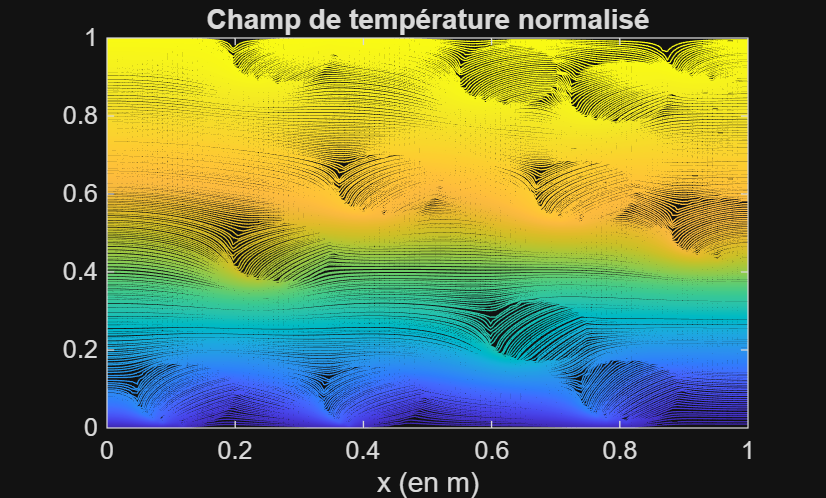


figure;
Tet=reshape(X,Ny,Nx);
Tet = flipud(Tet);                              % inverse l'ordre des lignes : la ligne 1 passe en haut du tracé
Nlev = 300;                        % Nombre de lignes de contour voulu
Ts = sort(Tet(:));                 % Un seul vecteur colonne, classé de la plus petite à la plus grande
niveaux = unique(Ts(round(linspace(1,numel(Ts),Nlev))));    % Niveaux équi-répartis en surface
contour(0:dx:Lx, 0:dy:Ly, Tet, niveaux)                     % Trace les isothermes aux niveaux choisis
title('Champ de température normalisé')
xlabel('x (en m)')

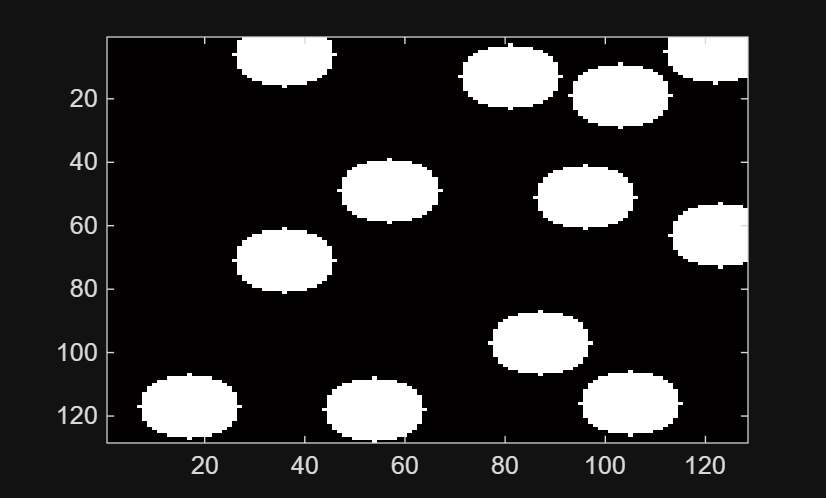



S = LoadMatrix(filename);
figure;
imagesc(full(S));
colormap(hot);



% Calcul du flux
% On calcule le flux sur chaque ligne

Phi = sum((k(1:Ny-1,:).*(Tet(2:Ny,:)-Tet(1:Ny-1,:)))*(dx/dy),2)

Phi =     9.3789
    9.6502
    9.1388
    9.8265
    9.5290
    9.4716
    8.9642
    8.6703
    8.8497
    9.2011
    9.1160
    9.1393
    9.1557
    8.2341
    6.9564
